## Initialize Directory


defaultDir = 'M:\Projects and Analysis\Papers\P2ry1'; %change if in a different location
cd(defaultDir);
addpath(genpath('MATLAB Functions'));
cd('Figure 2 - ISCs');


# Crenations

%data for room temperature Control and MRS washin
Confiles = loadFileList('.\Data\Crenations\P7_8\*Baseline.mat');
MRSfiles = loadFileList('.\Data\Crenations\P7_8\*MRS2500.mat');

WTareas = []; MRSareas = []; 
%load data and analyze
for i = 1:size(Confiles,1)
    load(Confiles{i})
    WTdata = [WTdata; {Crens.name mean(Crens.areas) size(Crens.locs([Crens.areas] > 500),1)/10}];
    WTareas = [WTareas; Crens.areas];
end
WTdata.Properties.VariableNames = {'Filename','CrenArea','CrenFreq'};

MRSdata = table();
for i = 1:size(MRSfiles,1)
    load(MRSfiles{i})
    MRSdata = [MRSdata; {Crens.name mean(Crens.areas) size(Crens.locs([Crens.areas] > 500),1)/10}];
    MRSareas = [MRSareas; Crens.areas];
end
MRSdata.Properties.VariableNames = {'Filename','CrenArea','CrenFreq'};

## Plot data

dim = [1.2 1.4];

[h, p] = compare2(WTdata.CrenFreq, MRSdata.CrenFreq, {'WT', 'MRS'},'Crenations per minute', dim,[5 12]);

   1.1719e-04



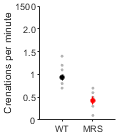

figure(h)
ylim([0 2.5])
yticks([0:0.5:2.5])
yticklabels({'0','0.5','1','1.5','2.0','1500'})
figQuality(gcf, gca, dim);
export_fig('.\EPS Panels\CrenFreq.eps',gcf);


[h, p] = compare2(WTdata.CrenArea, MRSdata.CrenArea,{'WT', 'MRS'}, 'Crenation Area (\mum^2)', dim,[5 12]);

   1.9803e-05



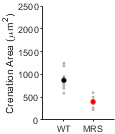

figure(h)
ylim([0 2500]);
yticks([0:500:2500]);
figQuality(gcf, gca, dim);
set(gca,'LooseInset',get(gca,'TightInset')) ;

%export_fig('.\EPS Panels\CrenArea.eps',gcf);

%data for physiological temp Control and MRS washin
Confiles = loadFileList('.\Data\Crenations\P7_MRS_CJK_PT\*Baseline.mat');
MRSfiles = loadFileList('.\Data\Crenations\P7_MRS_CJK_PT\*MRS2500.mat');

WTareas = []; MRSareas = []; 
%load data and analyze
WTdata = table();
for i = 1:size(Confiles,1)
    load(Confiles{i})
    WTdata = [WTdata; {Crens.name mean(Crens.areas) size(Crens.locs([Crens.areas] > 500),1)/10}];
    WTareas = [WTareas; Crens.areas];
end
WTdata.Properties.VariableNames = {'Filename','CrenArea','CrenFreq'};

MRSdata = table();
for i = 1:size(MRSfiles,1)
    load(MRSfiles{i})
    MRSdata = [MRSdata; {Crens.name mean(Crens.areas) size(Crens.locs([Crens.areas] > 500),1)/10}];
    MRSareas = [MRSareas; Crens.areas];
end
MRSdata.Properties.VariableNames = {'Filename','CrenArea','CrenFreq'};

## Plot data

dim = [1.2 1.4];

[h, p] = compare2P(WTdata.CrenFreq, MRSdata.CrenFreq, {'WT', 'MRS'},'Crenations per minute', dim,[5 12]);

   5.7483e-04



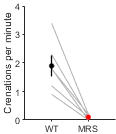

figure(h)
ylim([0 4])
yticks([0:1:4])
figQuality(gcf, gca, dim);
export_fig('.\EPS Panels\MRSCrenFreqPT.eps',gcf);


[h, p] = compare2P(WTdata.CrenArea, MRSdata.CrenArea,{'WT', 'MRS'}, 'Crenation Area (\mum^2)', dim,[5 12]);

    0.0062



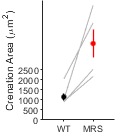

figure(h)
ylim([0 6000]);
yticks([0:500:2500]);
figQuality(gcf, gca, dim);
set(gca,'LooseInset',get(gca,'TightInset')) ;

%export_fig('.\EPS Panels\MRSCrenAreaPT.eps',gcf);

## Color plot

fnum = 5;
dim = [2.5 0.32];
WTfile = Confiles{fnum};
load(WTfile);
figaa = colorTicks(Crens.locs(Crens.areas > 500),600);
figQuality(gcf,gca, dim)
export_fig('.\EPS Panels\WTColor.eps',gcf);

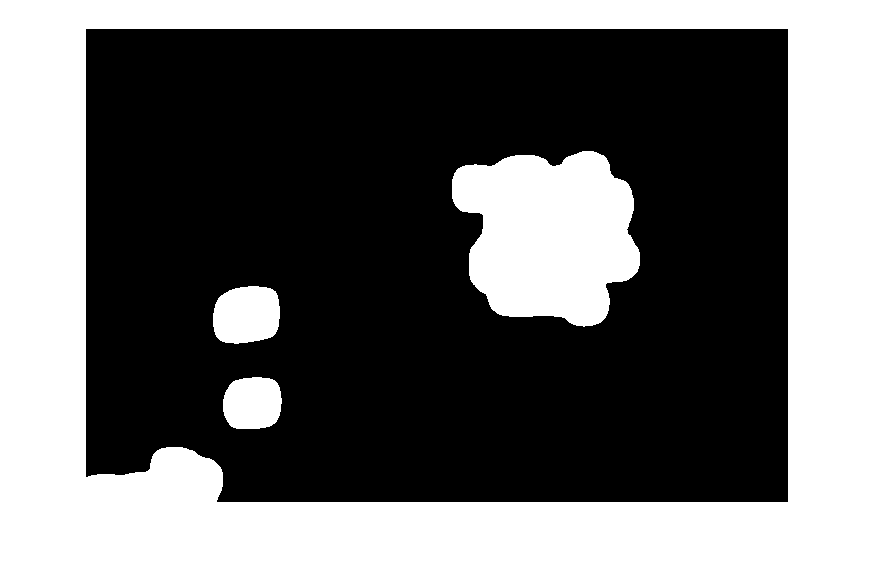

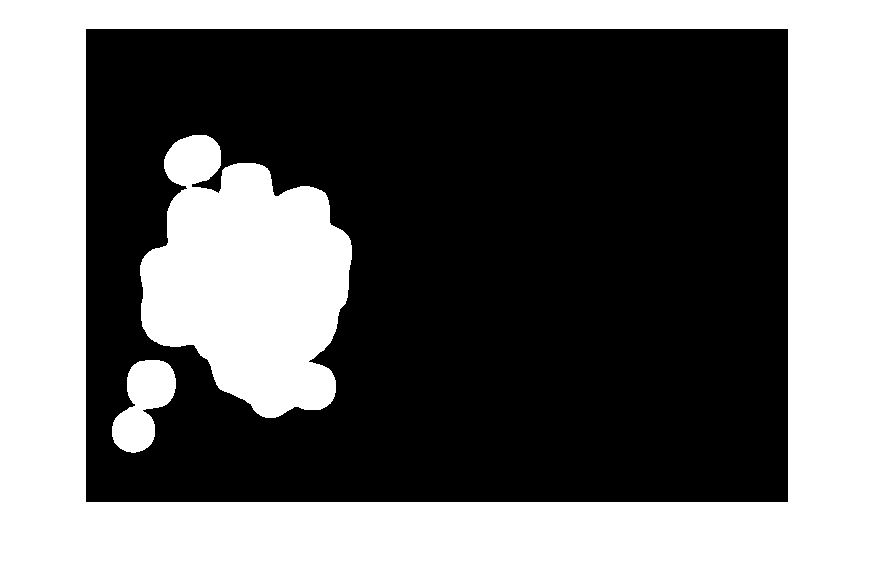


    WTthrTif = loadFileList(['.\Data\Crenations\P7_8\*_' num2str(fnum) '_*Baseline.tif']);
img = loadTif(WTthrTif{1},8);
events = getCrenationAreas(img,Crens.locs(Crens.areas > 500));

figure;
for i=1:size(events,3)
    imshow(events(:,:,i));
    export_fig(['.\EPS Panels\WTevents\' num2str(i) '.eps']);
end


 MRSfile = MRSfiles{fnum};
 load(MRSfile);
 figbb = colorTicks(Crens.locs(Crens.areas > 500),600);
 figQuality(gcf,gca, dim);
 export_fig('.\EPS Panels\MRSColor.eps',gcf);

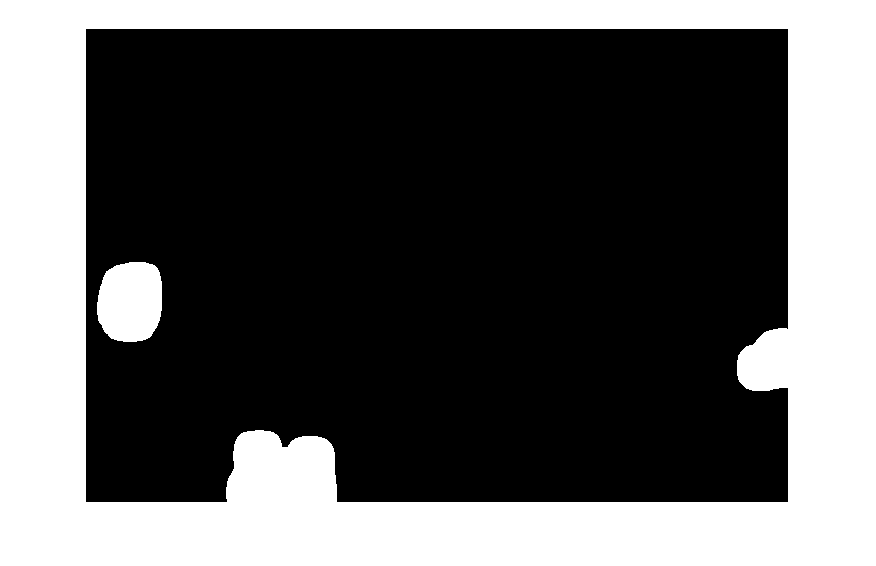

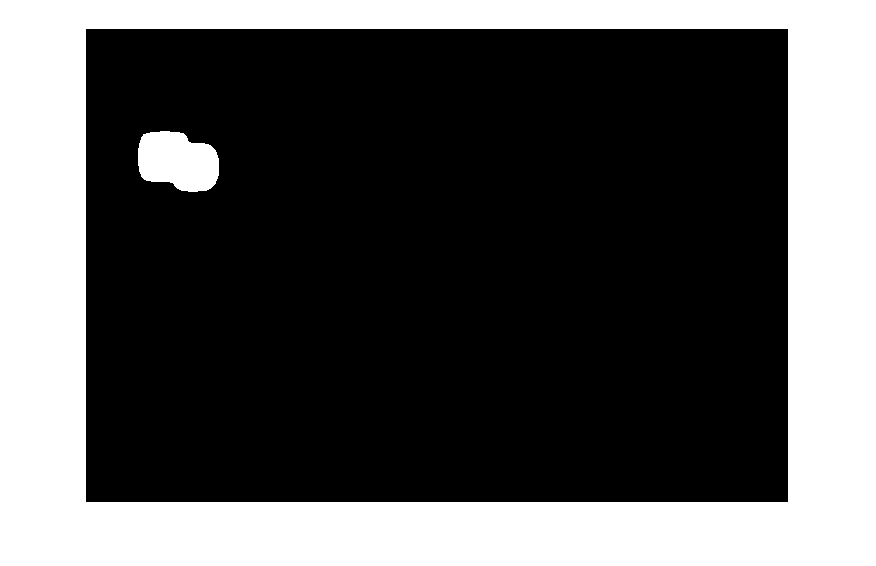

 
MRSthrTif = loadFileList(['.\Data\Crenations\P7_8\*_' num2str(fnum) '_*MRS2500.tif']);
img = loadTif(MRSthrTif{1},8);
events = getCrenationAreas(img,Crens.locs(Crens.areas > 500));

figure;
for i=1:size(events,3)
    imshow(events(:,:,i));
    export_fig(['.\EPS Panels\MRSevents\' num2str(i) '.eps']);
end

 
 
 MRStif = loadFileList(['.\Data\Crenations\P7_8\' num2str(fnum) '_*Baseline.tif']);
 img= loadTif(MRStif{1},8);

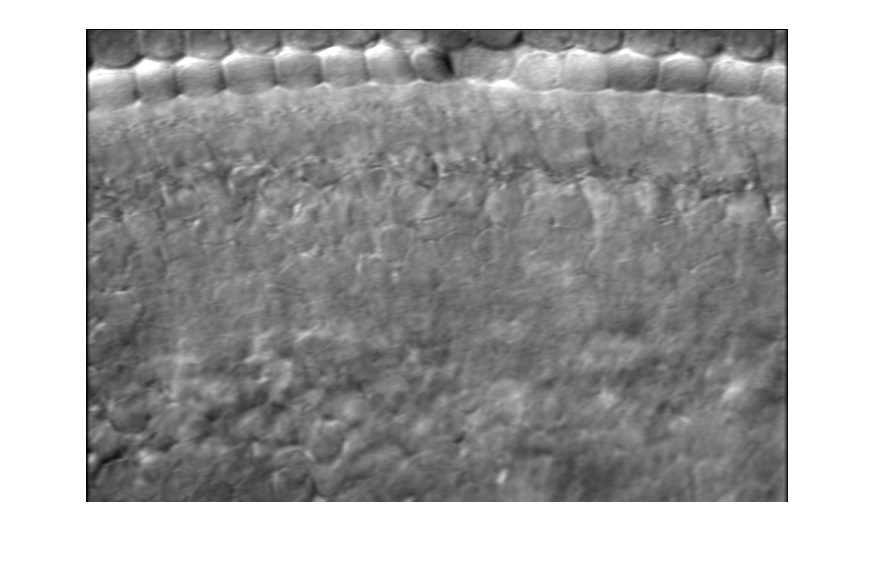

 figure;
 imshow(img(:,:,1));
 truesize;
 export_fig('.\EPS Panels\CrenationImg.eps');

 
 WTthrTif = loadFileList(['.\Data\Crenations\P7_8\*_' num2str(fnum) '_*Baseline.tif']);
 img = loadTif(WTtif{1},8);

Undefined variable "WTtif" or class "WTtif".

%data for room temp Control and KO 
Confiles = loadFileList('.\Data\Crenations\P7_8\*Baseline.mat');
KOfiles = loadFileList('.\Data\Crenations\P2ry1_KO\*Baseline.mat');

WTareas = []; KOareas = []; 
%load data and analyze
WTdata = table();
for i = 1:size(Confiles,1)
    load(Confiles{i})
    WTdata = [WTdata; {Crens.name mean(Crens.areas) size(Crens.locs([Crens.areas] > 500),1)/10}];
    WTareas = [WTareas; Crens.areas];
end
WTdata.Properties.VariableNames = {'Filename','CrenArea','CrenFreq'};

KOdata = table();
for i = 1:size(KOfiles,1)
    load(KOfiles{i})
    KOdata = [KOdata; {Crens.name mean(Crens.areas) size(Crens.locs([Crens.areas] > 500),1)/10}];
    KOareas = [KOareas; Crens.areas];
end
KOdata.Properties.VariableNames = {'Filename','CrenArea','CrenFreq'};

## Plot data

dim = [1.0 1.4];

[h, p] = compare2(WTdata.CrenFreq, KOdata.CrenFreq, {'WT', 'KO'},'Crenations per minute', dim,[5 12]);

    0.8182



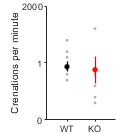

figure(h)
ylim([0 2])
yticks([0:1:2])
yticklabels({'0','1','2000'})
figQuality(gcf, gca, dim);
export_fig('.\EPS Panels\KOCrenFreqRT.eps',gcf);



[h, p] = compare2(WTdata.CrenArea, KOdata.CrenArea*3.6^2/5.8^2,{'WT', 'KO'}, 'Crenation Area', dim,[5 12]); %%correction on KO because incorrectly specified 3.6^2 instead of 5.8^2 um/pixel for Travis's rig

    0.0062



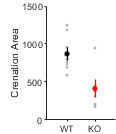

figure(h)
ylim([0 1500]);
yticks([0:500:1500]);
figQuality(gcf, gca, dim);
set(gca,'LooseInset',get(gca,'TightInset')) ;
export_fig('.\EPS Panels\KOCrenAreaRT.eps',gcf);

file = '.\Data\Crenations\P7_8\6_141212_Vid_28_Baseline.tif';
img = loadTif(file);

wtbaseimg = img(:,:,1)

wtbaseimg = 473×702 uint8 matrix
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
    15    27    71    78   100    95    92    84    76    69    65    64    65    68    71    73    72    72    68    64    58    55    50    47    45    48    49    52    55    59    63    68    71    75    77    78    78    77    76    75    75    72    73    73    76    75    73    69    62    56
    15    29    72    78    98    92    86    80    75    68    65    63    63    66    70    71    71    69    63    57    52    49    47    47    47    48    49    50    55    59    65    70    73    76    76    77    77    77    78    78    79    78    79    79    78    78    77    73    66    59
    14    24    66    72    91    87    84    82    77    72    

data = '.\Data\Crenations\P7_8\CrenationData_6_141212_Vid_28_Baseline.mat';
data = load(data);
WTCrens = data.Crens;

[h, h2] = drawCrenations(WTCrens.crenationImg(:,:,WTCrens.locs > 300),WTCrens.locs(WTCrens.locs > 300)-300,300,wtbaseimg)

h =   Figure (48) with properties:

      Number: 48
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [842 784 876 566]
       Units: 'pixels'

  Show all properties


h2 =   Figure (49) with properties:

      Number: 49
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [1000 918 560 420]
       Units: 'pixels'

  Show all properties


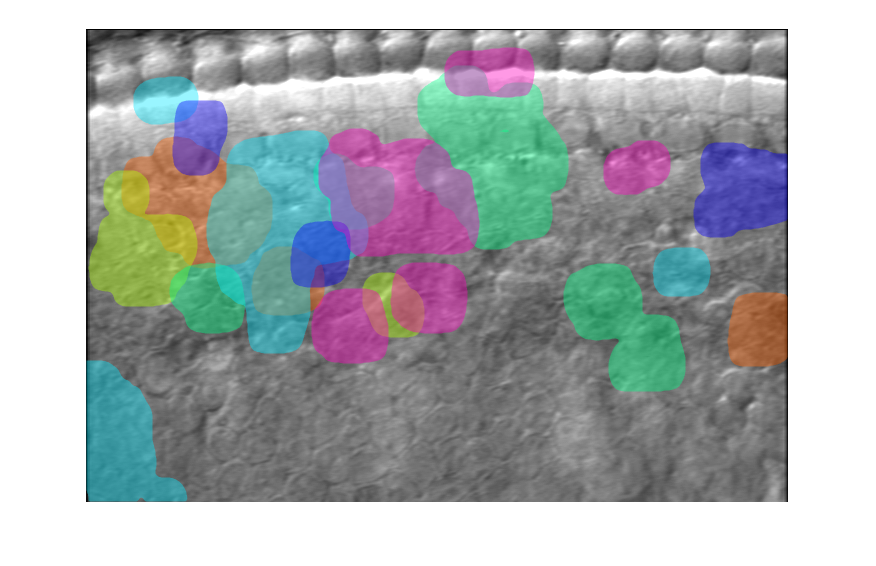

figure(h);
print(gcf, '-dpdf', '.\EPS Panels\WT_crenations.pdf')

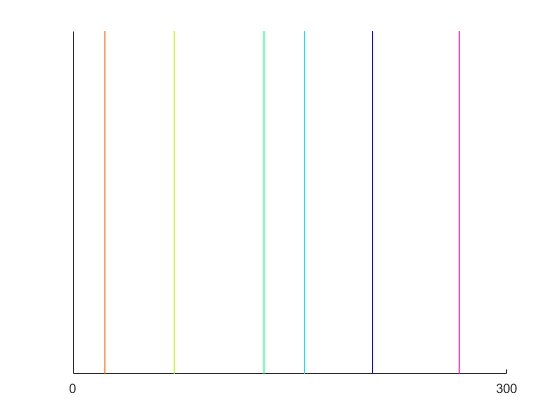

figure(h2);
print(gcf, '-dpdf', '.\EPS Panels\WT_crenations_timebar.pdf')


file = '.\Data\Crenations\P2ry1_KO\150501_Vid_006_P2RY1KO_Prep2.tif';
img = loadTif(file);

kobaseimg = img(:,:,1)

kobaseimg = 473×704 uint8 matrix
    25    17    68   123   116   129   134   142   150   158   163   164   166   169   168   162   150   142   138   136   134   132   130   132   136   141   147   152   156   155   156   163   169   173   174   174   176   180   182   185   184   180   175   170   169   172   178   178   167   149
    25    15    80   153   141   157   165   174   177   182   181   184   188   195   194   183   163   146   138   139   140   141   140   139   140   142   148   159   170   176   178   180   185   185   184   183   187   191   196   197   195   190   183   178   176   177   174   163   144   125
    24    15    89   175   168   186   190   196   195   197   199   205   213   218   214   196   171   149   137   132   133   135   137   138   139   143   155   170   183   188   191   191   188   183   178   180   184   187   192   194   193   190   182   174   167   162   153   143   129   118
    23    15   100   198   187   205   203   206   202   204   2

data = '.\Data\Crenations\P2ry1_KO\CrenationData_150501_Vid_006_P2RY1KO_Prep2_Baseline.mat';
data = load(data);
KOCrens = data.Crens;

[h, h2] = drawCrenations(KOCrens.crenationImg(:,:,KOCrens.locs<300),KOCrens.locs(KOCrens.locs<300),300,kobaseimg)

h =   Figure (50) with properties:

      Number: 50
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [841 784 878 566]
       Units: 'pixels'

  Show all properties


h2 =   Figure (51) with properties:

      Number: 51
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [1000 918 560 420]
       Units: 'pixels'

  Show all properties


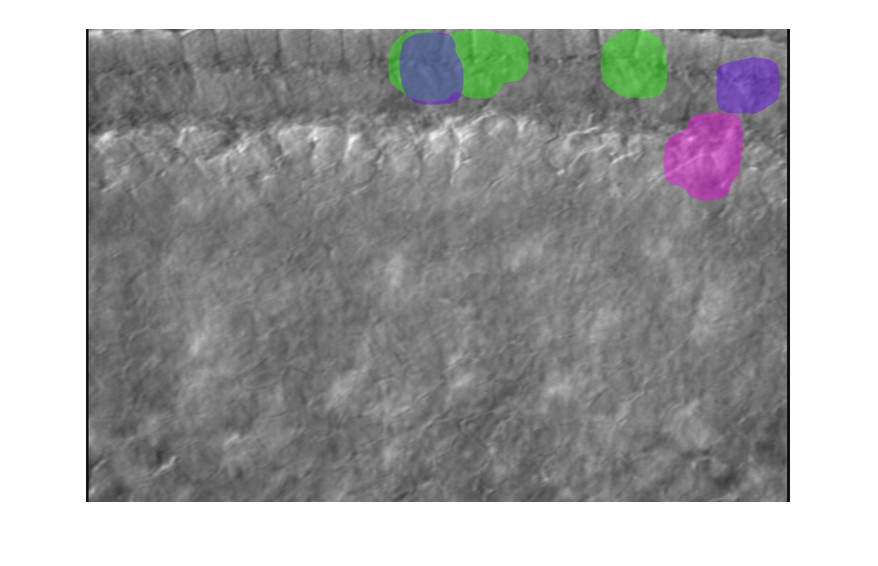

figure(h);
print(gcf, '-dpdf', '.\EPS Panels\KO_crenations.pdf')

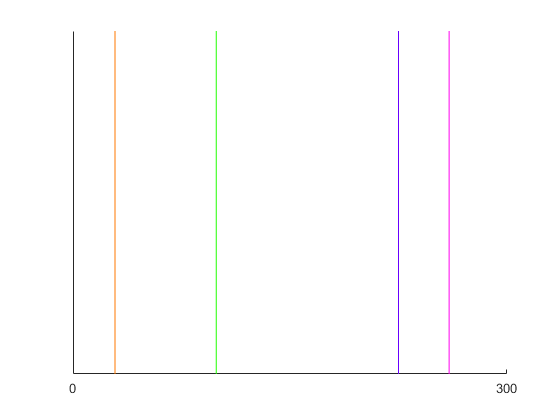

figure(h2);
print(gcf, '-dpdf', '.\EPS Panels\KO_crenations_timebar.pdf')

%export_fig